# **Figure 4**

This m-file is written according  to  the paper entitled :

 "**An Efficient Low-Complexity Method to Calculate Hybrid Beamforming Matrices for mmWave Massive MIMO Systems**" 

you can see the paper on this link:  [https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9442813](https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9442813)

## **Authors: **

**1- Jamal Beiranvand** 

    Website: 

    e-mail: Jamalbeiranvand@gmail.com

    google scholar:  [https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en](https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en)

2- **Vahid Meghdadi**

    website: [https://www.unilim.fr/pages_perso/vahid/](https://www.unilim.fr/pages_perso/vahid/) 

    e-mail: meghdadi@ensil.unilim.fr

    google scholar:  [https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en](https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en)

## Required Functions to run

All functions used in this code are in the** "Functions" **folder, described in the **"MATLAB Functions" **document.

**Note: **You have to change  the path of **Functions** folder according its path in your PC.

Date : 02/07/2021

By Jamal Beiranvand

## Initialize

clear
clc
Nt=36:256;
Ns=10;
Niter=10;

## Main Code

%%
N=8;
FPS_8=Niter*(Ns^3+Nt.*Ns.*N.*log2(Nt.*Ns.*N));
Proposed_8=Ns^3+Nt.*Ns*(3^(N/2)/N);
%%
N=12;
FPS_12=Niter*(Ns^3+Nt.*Ns.*N.*log2(Nt.*Ns.*N));
Proposed_12=Ns^3+Nt.*Ns*(3^(N/2)/N);
%%
N=16;
FPS_16=Niter*(Ns^3+Nt.*Ns.*N.*log2(Nt.*Ns.*N));
Proposed_16=Ns^3+Nt.*Ns*(3^(N/2)/N);


## plot

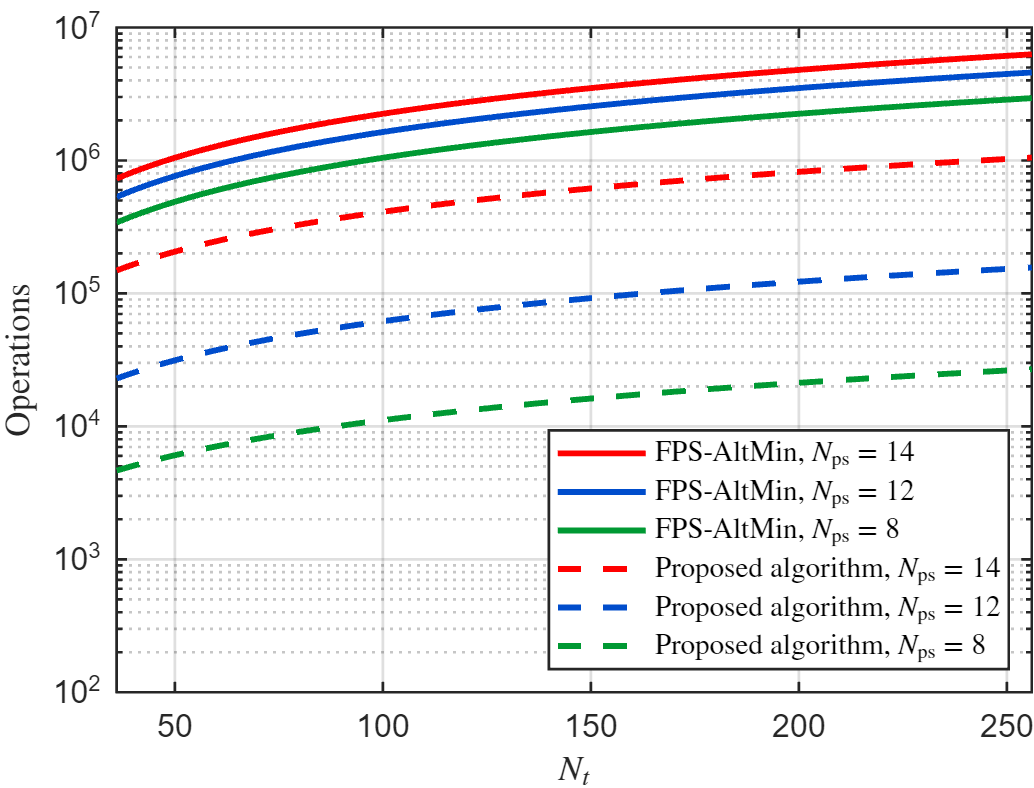

 Xaxis=Nt;
Fig=figure;
P1=semilogy(Xaxis,FPS_16);
hold on
P2=semilogy(Xaxis,FPS_12);
P3=semilogy(Xaxis,FPS_8);
P4=semilogy(Xaxis,Proposed_16);
P5=semilogy(Xaxis,Proposed_12);
P6=semilogy(Xaxis,Proposed_8);

Legend1='FPS-AltMin, $N_{\mathrm{ps}}=14$';
Legend2='FPS-AltMin, $N_{\mathrm{ps}}=12$';
Legend3='FPS-AltMin, $N_{\mathrm{ps}}=8$';
Legend4='Proposed algorithm, $N_{\mathrm{ps}}=14$';
Legend5='Proposed algorithm, $N_{\mathrm{ps}}=12$';
Legend6='Proposed algorithm, $N_{\mathrm{ps}}=8$';

% P1 properties
set(P1,'LineStyle','-');           % '-' , '--' , ':' , '-.' , 'none'
set(P1,'Marker','none');       % 'o' , '+'  , '*' , 'x' ,'s' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram', 'none'
set(P1,'LineWidth',2);
set(P1,'Color','r');
set(P1,'MarkerSize',10);
P1_group= hggroup;set(P1,'Parent',P1_group);
set(get(get(P1_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on'); 
% P1.MarkerIndices =[ 1 6];

% P2 properties
set(P2,'LineStyle','-');           % '-' , '--' , ':' , '-.'
set(P2,'Marker','none');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P2,'LineWidth',2);
set(P2,'Color',[0 .3 .8]);
set(P2,'MarkerSize',12);
P2_group= hggroup;set(P2,'Parent',P2_group);
set(get(get(P2_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');

% % % P2 properties
set(P3,'LineStyle','-');           % '-' , '--' , ':' , '-.'
set(P3,'Marker','none');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P3,'LineWidth',2);
set(P3,'Color',[.0 .6 .2]);
set(P3,'MarkerSize',10);
P3_group= hggroup;set(P3,'Parent',P3_group);
set(get(get(P3_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% % 
% % P2 properties
set(P4,'LineStyle','--');           % '-' , '--' , ':' , '-.'
set(P4,'Marker','none');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P4,'LineWidth',2);
set(P4,'Color','r');
set(P4,'MarkerSize',7);
P4_group= hggroup;set(P4,'Parent',P4_group);
set(get(get(P4_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 
% % P2 properties
set(P5,'LineStyle','--');           % '-' , '--' , ':' , '-.'
set(P5,'Marker','none');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P5,'LineWidth',2);
set(P5,'Color',[0 .3 .8]);
set(P5,'MarkerSize',7);
P5_group= hggroup;set(P5,'Parent',P5_group);
set(get(get(P5_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 
set(P6,'LineStyle','--');           % '-' , '--' , ':' , '-.'
set(P6,'Marker','none');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P6,'LineWidth',2);
set(P6,'Color',[.0 .6 .2]);
set(P6,'MarkerSize',7);
P6_group= hggroup;set(P6,'Parent',P6_group);
set(get(get(P6_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');


lgd=legend(Legend1,Legend2,Legend3,Legend4,Legend5,Legend6);
% Axes Properties 
ax=gca;
ax.XLim = [min(Xaxis) max(Xaxis)];
 ax.YLim = [1e2 1e7];
% ax.XTick = Xaxis;
% ax.XTickLabel=Xaxis;
ax.XLabel.String='$N_t$';
ax.YLabel.String='Operations';
ax.XGrid='on';
ax.YGrid='on';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
ax.YLabel.Interpreter='latex';
ax.XLabel.Interpreter='latex';
ax.FontSize = 11;
ax.LineWidth = .9;
ax.Box='on';

% Legend Properties %
lgd.Location= 'southeast'; %%
lgd.Box='on';
lgd.LineWidth=.9;
lgd.Interpreter='latex';
lgd.FontSize = 10;
% 
% Figure Properties
ax.Units='centimeters';
ax.Position = [ax.TightInset(1)+ax.TightInset(3) ax.TightInset(2) 11 8];
Fig.Units='centimeters';
Fig.Position = [10 5 (ax.TightInset(1)+ 2*ax.TightInset(3)+ ax.Position(3) ) (ax.TightInset(2)+ ax.TightInset(4)+ ax.Position(4))];


%  Creat notation 
% Not1=annotation('textbox');
% X_points=[-28 0];
% Y_points=[ .5*(diff(ax.YLim)) .75*(diff(ax.YLim))];
% str1=['UPA structure at Tx: ',num2str(Tx(1)),'$\times$',num2str(Tx(2))];
% str2=['UPA structure at Rx: ',num2str(Rx(1)),'$\times$',num2str(Rx(2))];
% str3=['$N_{s}=$ ',num2str(Ns),',  $N_{RF}=$ ',num2str(NRF)];
% str4=['$N_{cl}=$ ',num2str(Ncl),',  $N_{ray}=$ ',num2str(Nray)];
% Not1.String={str1,str2,str3,str4};
% Not1.FontSize = 10;
% Not1.Interpreter='latex';
% Not1.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Not1.Position=[x_begin y_begin  x_End y_End];
% % % % 
% % 
% % Ell=annotation('ellipse');
% % X_points=[19 21];
% % Y_points=[25 55];
% % Ell.Units='centimeters';
% % Dx=ax.Position(3)/(diff(ax.XLim));
% % Dy=ax.Position(4)/(diff(ax.YLim));
% % x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% % y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% % x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% % y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% % Ell.Position=[x_begin y_begin  x_End y_End];
% % 
% Textarrow1=annotation('textarrow');
% X_points=[8 8];
% Y_points=[10 47];
% str1=['$b=$',num2str(Bits(3))];
% Textarrow1.String={str1};
% Textarrow1.Interpreter='latex';
% Textarrow1.FontSize = 10;
% Textarrow1.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Textarrow1.Position=[x_begin y_begin  x_End y_End];
% % %%
% % Ell2=annotation('ellipse');
% % X_points=[19 21];
% % Y_points=[90 125];
% % Ell2.Units='centimeters';
% % Dx=ax.Position(3)/(diff(ax.XLim));
% % Dy=ax.Position(4)/(diff(ax.YLim));
% % x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% % y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% % x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% % y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% % Ell2.Position=[x_begin y_begin  x_End y_End];
% % 
% Textarrow2=annotation('textarrow');
% X_points=[16 16];
% Y_points=[10 56];
% str1=['$b=$',num2str(Bits(2))];
% Textarrow2.String={str1};
% Textarrow2.Interpreter='latex';
% Textarrow2.FontSize = 10;
% Textarrow2.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Textarrow2.Position=[x_begin y_begin  x_End y_End];
% % %%
% % Ell3=annotation('ellipse');
% % X_points=[19 21];
% % Y_points=[140 185];
% % Ell3.Units='centimeters';
% % Dx=ax.Position(3)/(diff(ax.XLim));
% % Dy=ax.Position(4)/(diff(ax.YLim));
% % x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% % y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% % x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% % y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% % Ell3.Position=[x_begin y_begin  x_End y_End];
% % 
% Textarrow3=annotation('textarrow');
% X_points=[24 24];
% Y_points=[10 52];
% str1=['$b=$',num2str(Bits(1))];
% Textarrow3.String={str1};
% Textarrow3.Interpreter='latex';
% Textarrow3.FontSize = 10;
% Textarrow3.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Textarrow3.Position=[x_begin y_begin  x_End y_End];
